# **Controls for parameter tuning**

Linear classification

Holdout 50 or 80% --> community uses 80%

 --> maybe check a few cells

============

OBSERVATIONS

============

Analysis on MODULATION

==> WHAT ABOUT PEAK MAGNITUDE

==> WHAT NOT JUST THE PEAKS (full signal)

-  Encoder

-  EyeCam_Wheel --> check against encoder

-  L Forelimb

-  R Forelimb

-  Trunk (highest for 3-4 cells, so keep for now)

-  BodyCam LWhisker : The good one (behind, on black background)

- BodyCam RWhisker (on the whiskerpad, from the front + cuetip)

- Perioral

- trigger

- F0

**  shuffles (temporal and spatial permutation, separately, for all Conditions)

Excluded : 

- Laser

- BodyCam Eye --> meh

- Eycam whiskerpad (just check 09-12 exp 9-11 exp2 04-30-exp4

- eyecam Eye (check 09-04 exp2)

- NOT RT3D_MC BUT BASELINE F0 instead

============

PREDICTORS

============

* All ROIs

* Highest PHATE (+ and - for PHATEs 1-3)

* Perisomatic ROIS (6)

* 6 random ROIs 

* High PHATES GROUPS (6 ROIs of the PHATES 1->3 + and -)

s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

# 1. Load experiment

% note : the experiment loaded here has been preprocessed for peak detection and
% rescaling. If this is not the case, you need to do it.
load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_final_new_zscored_compressed\2019-11-05_exp_3\2019-11-05_exp_3.mat')


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 


ans = 1

%load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_final_new_zscored_compressed\2019-10-31_exp_1\2019-10-31_exp_1.mat')

# 2. Define the Analysis Settings

## Arboreal Scan settings

obj.detrend     = 0;% -1; %'auto'
obj.filter_win  = -1; % 


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 


total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um


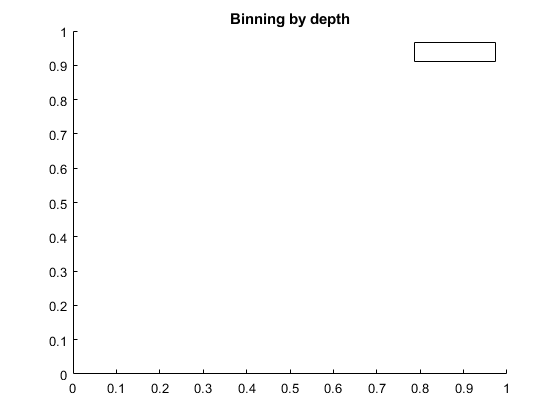

Now detecting events with global pairwise correlation at least > 0.2 % 
    * Events detection is using PAIRWISE CORRELATION between all provided traces 
      Epochs of correlated changes of activity across a set % of the tree/pop will be considered as an event 


THR_FOR_GLOBAL = 0.5000

    * Events occuring in > 50% of the tree are considered global 
    * Maximal tree correlation is 85.2294%. A values < 100% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
      This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes that the entire tree CAN be correlated 
    * 295 events have been detected 
    * Peak times were extracted on the scaled avrage of all traces, but using the event times obtained with the global pairwise correlation. A jitter of 66.6667 ms was tolerated around the correated peak time 
    * 0events were of large enough amplitude to be detected on the averaged traces, but were not corrlated across the entire tree 


THR_FOR_CONNECTION = 0.2000

* Now detecting ROIs that are either,
      - so poorly correlated to the rest of the tree that they probably belong to another cell (or have no signal).
      - are member of batch_params.excluded_branches 
* Threshold for exclusion is  0.2 % 


RECOVERY_THR = 0.8000

ans = 15660×1 single column vector
   16.2037
   15.6205
   13.7397
   11.8488
   10.8633
    9.3598
    8.3145
    7.4186
    5.8599
    4.6029


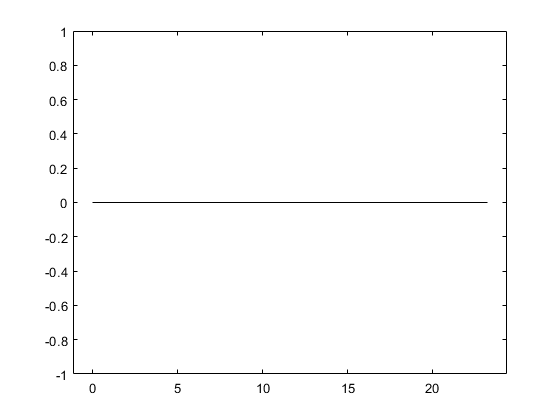

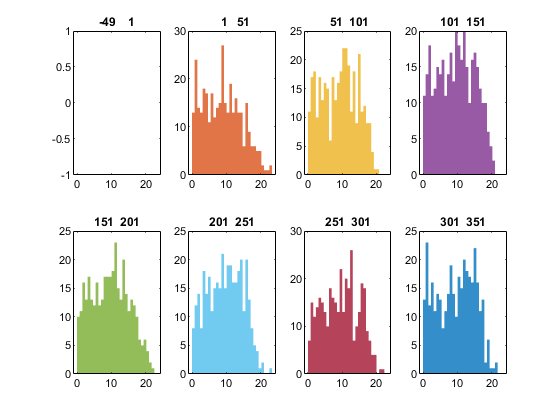

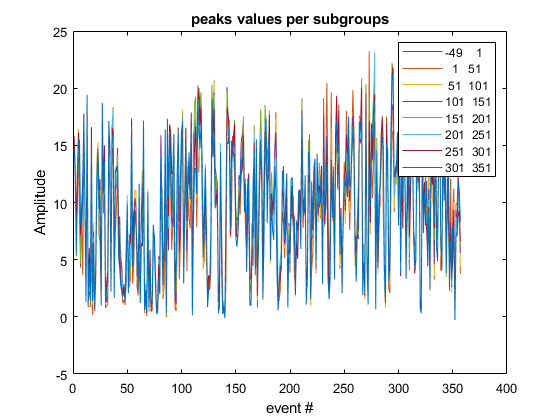

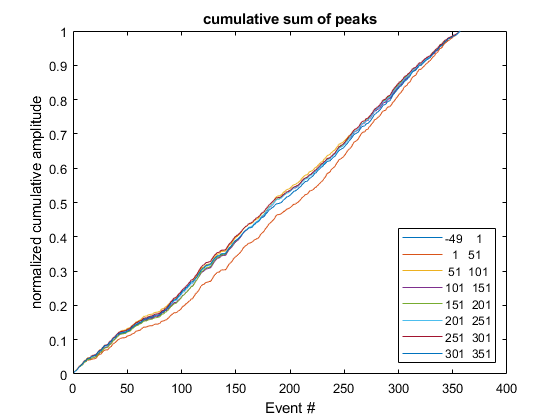

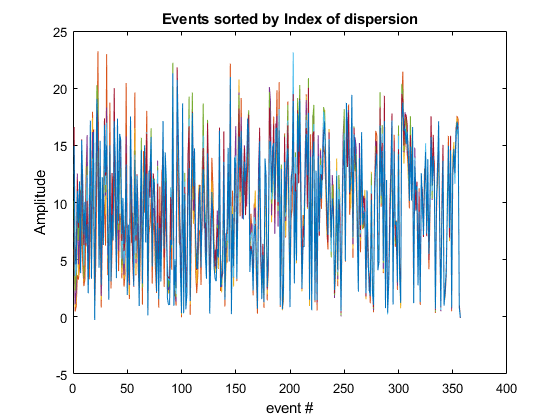

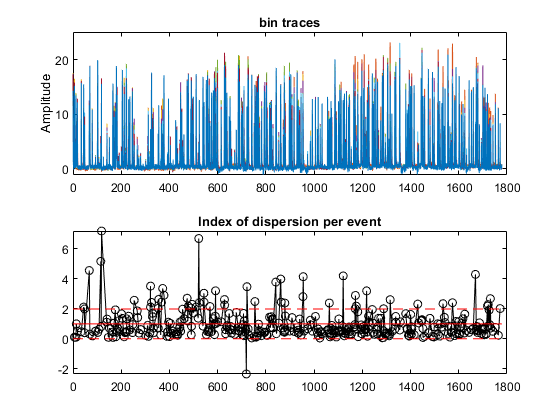

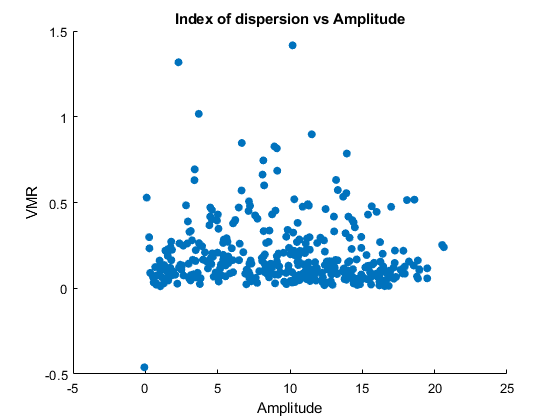

ans = 357×1 single column vector
    0.1108
    0.1028
    1.0009
    0.4976
    0.4761
    2.1160
    1.9923
    0.4056
    4.5454
    0.3160


Using current obj.cc_mode
Using current obj.cc_mode : groups_peaks


Doing PCA
PCA using random SVD
PCA took 0.040707 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 162
First iteration: k = 100
Number of samples below the threshold from 1st iter: 162
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.15556 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 31


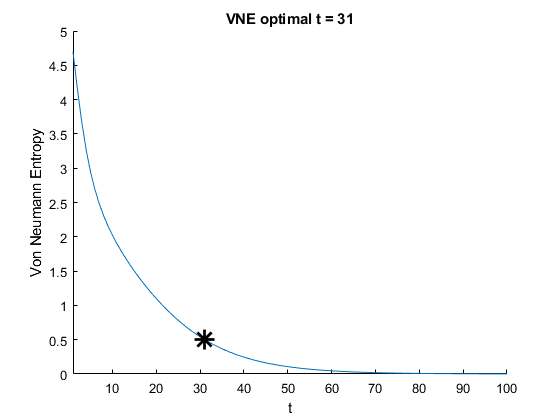

Diffusing operator
Diffusion took 0.0087245 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.035599 seconds
Doing classical MDS
CMDS took 0.013681 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.883502       0.0323745
           1        0.304117       0.0161775         10.2508              10
           2        0.253538        0.017608         4.67548               9
           3        0.162193       0.0256775         7.83784              13
           4       0.0995856       0.0235272         2.81742              10
           5       0.0656247       0.0188668         1.91057               9
           6       0.0464475       0.0180973         1.36528               9
           7        0.035186 

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

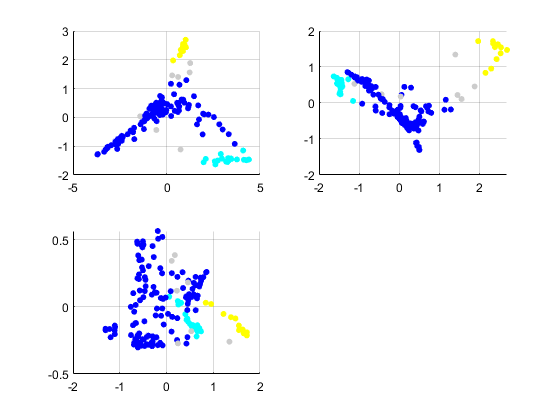

obj = Using current obj.cc_mode : groups_peaks
  arboreal_scan_experiment with properties:

         extraction_method: 'median'
             source_folder: 'C:/Users/THE BEASTWO/Documents/MATLAB/arboreal_scans_final_new_zscored_compressed/2019-10-01_exp_1/'
             update_folder: ''
      extracted_data_paths: {1×30 cell}
               need_update: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
            arboreal_scans: {1×30 cell}
                 timescale: [1×1 struct]
                      demo: 0
        auto_save_analysis: 1
         auto_save_figures: 0
                filter_win: [9 0]
               filter_type: 'gaussian'
              dim_red_type: 'pca'
                  peak_thr: 2
               bad_ROI_thr: 0.2000
                   cc_mode: 'groups_peaks'
                   detrend: 0
              is_detrended: 1
               is_rescaled: 1
            default_han

total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-exc

obj.rendering   = 0;
obj.process({'distance',50},[-1, 0]); %% Add grouping settings here

Doing PCA
PCA using random SVD
PCA took 0.010766 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 162
First iteration: k = 100
Number of samples below the threshold from 1st iter: 162
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.017702 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 31


Diffusing operator
Diffusion took 0.0067768 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.005172 seconds
Doing classical MDS
CMDS took 0.0038545 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.883503        0.032374
           1        0.304122       0.0161827         10.2535              10
           2        0.253528       0.0176126         4.67617               9
           3         0.16222       0.0256737         7.83394              13
           4         0.09958       0.0235144         2.81816              10
           5       0.0656362       0.0188696         1.90984               9
           6       0.0464508       0.0180991          1.3655               9
           7       0.0351846

perisomatic_ROIs= num2cell(obj.ref.indices.somatic_ROIs); % if not using num2cell, persiomatic signal will be averaged

obj.get_dimensionality([],'phate','peaks_subtracted',[]);

## Machine Learning settings

use_classifier  = false;
method          = 'linear';
variable_type   = 'peaks_subtracted';

variable_type = 'peaks_subtracted'

%behaviours      = {'encoder','EyeCam_Wheel','EyeCam_L_forelimb','EyeCam_R_forelimb','BodyCam_Trunk','BodyCam_L_whisker','BodyCam_R_whisker','EyeCam_Perioral','trigger','baseline'}
behaviours      = {'encoder','EyeCam_L_forelimb','EyeCam_R_forelimb','BodyCam_L_whisker','BodyCam_R_whisker','EyeCam_Perioral','trigger','baseline'};

behaviours = 1×8 cell array
    {'encoder'}    {'EyeCam_L_forelimb'}    {'EyeCam_R_forelimb'}    {'BodyCam_L_whisker'}    {'BodyCam_R_whisker'}    {'EyeCam_Perioral'}    {'trigger'}    {'baseline'}


N_iter          = 10;
KFold           = 5;
holdout         = 0.3; 

rendering       = 0; % set to 1 to see individual predictions

# 3. Regular Behaviour Prediction

## On all ROIs

detrend_behaviours = logical
   1


smooth_behaviours = 1


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic 

THR_FOR_GLOBAL = 0.5000

    * Events occuring in > 50% of the tree are considered global 
    * Maximal tree correlation is 71.5993%. A values < 100% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
      This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes that the entire tree CAN be correlated 
    * 312 events have been detected 
    * Peak times were extracted on the scaled avrage of all traces, but using the event times obtained with the global pairwise correlation. A jitter of 66.6667 ms was tolerated around the correated peak time 
    * 1events were of large enough amplitude to be detected on the averaged traces, but were not corrlated across the entire tree 


THR_FOR_CONNECTION = 0.2000

* Now detecting ROIs that are either,
      - so poorly correlated to the rest of the tree that they probably belong to another cell (or have no signal).
      - are member of batch_params.excluded_branches 
* Threshold for exclusion is  0.2 % 


RECOVERY_THR = 0.8000

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


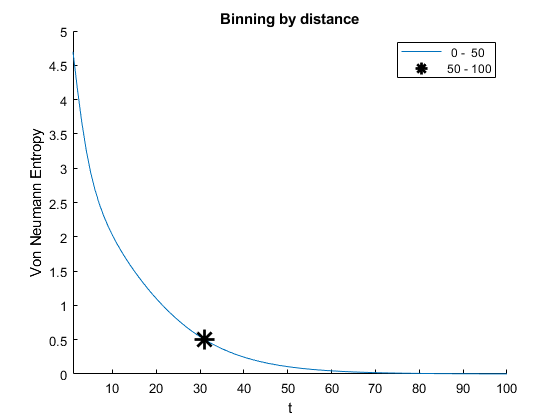

detrend_behaviours = logical
   1


smooth_behaviours = 1

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


detrend_behaviours = logical
   1


smooth_behaviours = 1

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


detrend_behaviours = logical
   1


smooth_behaviours = 1

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


detrend_behaviours = logical
   1


smooth_behaviours = 1

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


detrend_behaviours = logical
   1


smooth_behaviours = 1

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


detrend_behaviours = logical
   1


smooth_behaviours = 1

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


detrend_behaviours = logical
   1


smooth_behaviours = 1

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


detrend_behaviours = logical
   1


smooth_behaviours = 1

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


detrend_behaviours = logical
   1


smooth_behaviours = 1

timepoints =           52          67         106         119         121         159         304         390         419         424         596         617         704         823         905         952        1016        1032        1044        1230        1244        1332        1457        1466        1504        1549        1576        1589        1603        1615        1654        1692        1701        1773        1808        1813        1817        1875        1908        1909        1950        1956        1959        1967        2040        2084        2169        2173        2177        2190


result_linear = {}; 
for iter = 1:N_iter
    result_linear{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, '', 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold);
end

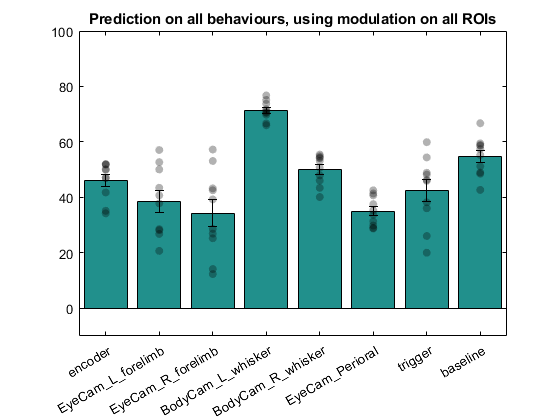

bar_chart(result_linear, 'beh_type');title('Prediction on all behaviours, using modulation on all ROIs')

## On high phates

N_phates        = 3;
cutoff          = 10; % 0 is just min and max
bidirectional   = true;
try
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
catch
    obj.get_dimensionality([],'phate','peaks_subtracted',[]);
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
end

% to study phates 1-3 up/down together and avg'd across ROIs (e.g. contents of cell array are avg'd prior to running ML) 
% e.g. if the cell 'cares' about avg. signals coming out of larger than our ROIs compartments
results_high_phate = {}; 
for iter = 1:N_iter
    results_high_phate{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, groups, 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold);
end
bar_chart(results_high_phate, 'beh_type');title('Prediction on all behaviours, using modulation on High Phates')

% to study phate 1,2 or 3 up or down in isolation (e.g. phate 1 up only) or clusters (e.g. DBSCAN)
% need to know what is in groups for this to be interpretable
for jj = 1:numel(groups)
    groups{jj}

results_high_phate = {}; 
for iter = 1:N_iter
    results_high_phate{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, groups{jj}, 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold);
end
bar_chart(results_high_phate, 'beh_type');title('Prediction on all behaviours, using modulation on High Phates')
end

%to study combos of phate groups (e.g. phate 1-3 up/up/up, phate 1-3 down/down/down, phate 1 up/down, phate 2 up/down, phate 3 up/down)
prepare_test_groups    % this generates lists of ROIs defined by up/down phate cutoff 
for jj = 1:numel(test_groups)
    test_groups{jj}

results_high_phate = {}; 
for iter = 1:N_iter
    results_high_phate{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, test_groups{jj}, 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold);
end
bar_chart(results_high_phate, 'beh_type');title('Prediction on all behaviours, using modulation on High Phates')
end

## On perisomatic ROIs

results_high_phate = {}; 
for iter = 1:N_iter
    results_high_phate{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, perisomatic_ROIs, 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold);
end
bar_chart(results_high_phate, 'beh_type');title('Prediction on all behaviours, using modulation on perisomatic ROIs')


## On random ROIs

results_random = {}; 
for iter = 1:N_iter
    results_high_phate{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, perisomatic_ROIs, 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold);
end
bar_chart(results_high_phate, 'beh_type');title('Prediction on all behaviours, using modulation on perisomatic ROIs')

# 4. Time Shuffling

% Using the entire dendritic tree on the encoder
time_shuff_results = {};
for iter = 1:N_iter
    time_shuff_results{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, '', 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold,'shuffling','events');
end
bar_chart(time_shuff_results, 'beh_type');title('Prediction on all behaviours, using modulation on all ROIs, but Ca2+ events are shuffled')


# 5. Spatial Shuffling

% Using the entire dendritic tree on the encoder
space_shuff_results = {};
for iter = 1:N_iter
    space_shuff_results{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, '', 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold,'shuffling','ROIs');
end
bar_chart(space_shuff_results, 'beh_type');title('Prediction on all behaviours, using modulation on all ROIs, but for each event modulation values are shuffled between ROIs')


# 6. Trial Shuffling

% Using the entire dendritic tree on the baseline and encoder
trial_shuff_results = {}; 
shuffled_beh  = strcat(behaviours, '_shuffle');
shuffled_beh = reshape([behaviours; shuffled_beh],[],1)';
%shuffled_beh  = {'encoder','encoder_shuffle','EyeCam_L_forelimb','EyeCam_L_forelimb_shuffle','EyeCam_R_forelimb','EyeCam_R_forelimb_shuffle','BodyCam_L_whisker','BodyCam_L_whisker_shuffle','BodyCam_R_whisker','BodyCam_R_whisker_shuffle','EyeCam_Perioral','EyeCam_Perioral_shuffle','trigger','trigger_shuffle','baseline','baseline_shuffle'};

shuffled_beh = 1×16 cell array
    {'encoder'}    {'encoder_shuffle'}    {'EyeCam_L_forelimb'}    {'EyeCam_L_forelimb_shuffle'}    {'EyeCam_R_forelimb'}    {'EyeCam_R_forelimb_shuffle'}    {'BodyCam_L_whisker'}    {'BodyCam_L_whisker_shuffle'}    {'BodyCam_R_whisker'}    {'BodyCam_R_whisker_shuffle'}    {'EyeCam_Perioral'}    {'EyeCam_Perioral_shuffle'}    {'trigger'}    {'trigger_shuffle'}    {'baseline'}    {'baseline_shuffle'}


%shuffled_beh  = {'baseline','baseline_shuffle','encoder'}

%variable_type = 1:100:15000 % mimics the slow baseline drift measurement

% need to convert the time points t into amplitudes for valid ROIs, then
% feed this to variable_type
% below is just a first approx/ball park estimate:

tt = find(obj.get_tp_for_condition('quiet'))
num_ev = numel(vertcat(obj.event.peak_time{:})); %could use this or several other of the obj.event outputs to get # of events
variable_type = sort(tt(randi(numel(tt),1,num_ev)))

for iter = 1:N_iter
    result_linear{iter} = predict_behaviours(obj, false, 'linear', variable_type, shuffled_beh, '', 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold);
end

detrend_behaviours = logical
   1


smooth_behaviours = 1

block_size = 522

block_size = 522

block_size = 522

block_size = 522

block_size = 522

block_size = 522

block_size = 522

block_size = 522

bar_chart(result_linear, 'beh_type');title('Prediction selected behaviours with and without shuffling, using modulation on all ROIs')
% figure();plot(obj.rescaled_traces(:,77));hold on;scatter(variable_type, obj.rescaled_traces(variable_type,77),'r','filled')

5. Control based on the baseline behaviour

- h-word

- test if Ca is dirtributed normally (it should be, almost)

% run some (n = 16) key controls (e.g. do ML fo all ROIs with peaks_subtracted, raw_peaks, raw, raw_queit, quiet_subtracted
% plus a few shuffles where most relevant)
run_ML_controls






% plot_prediction(out{1}.calcium, out{1}.bin_beh{1}, out{1}.peak_tp{1}, out{1}.train_range{1}, out{1}.prediction{1}, out{1}.full_beh{1} , out{1}.beh_type{1}, out{1}.score{1});
